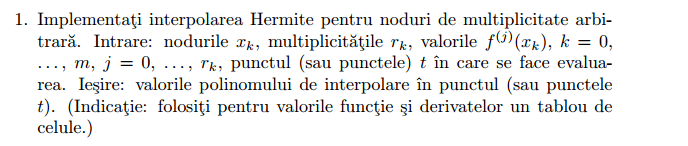

## HermitePowellMultipoints POC

f  = @(x) sin(pi*x/2) + 1;
df = @(x) (pi/2)*cos(pi*x/2);

x  = [0, 1, 2];
y  = f(x);
dy = df(x);

% xx = [0.25, 0.5, 1.5, 1.75];
xx = linspace(0.1, 2, 10);

[Hs, Qs] = HermitePowellMultipoints(x, y, dy, xx);

table(xx.', Hs.', 'VariableNames', {'x', 'P_H(x)'})

ans = 10×2 table
       x       P_H(x)
    _______    ______

        0.1     1.157
    0.31111    1.4719
    0.52222    1.7339
    0.73333    1.9147
    0.94444    1.9963
     1.1556    1.9707
     1.3667    1.8406
     1.5778    1.6184
     1.7889    1.3272
          2         1


for i = 1:numel(xx)
    fprintf('\nDivided-difference table Qs{%d} (for x = %.2f):\n', i, xx(i));
    disp(Qs{i});
end


Divided-difference table Qs{1} (for x = 0.10):


    1.0000         0         0         0         0         0
    1.0000    1.5708         0         0         0         0
    2.0000    1.0000   -0.5708         0         0         0
    2.0000    0.0000   -1.0000   -0.4292         0         0
    1.0000   -1.0000   -1.0000         0    0.2146         0
    1.0000   -1.5708   -0.5708    0.4292    0.2146   -0.0000




Divided-difference table Qs{2} (for x = 0.31):


    1.0000         0         0         0         0         0
    1.0000    1.5708         0         0         0         0
    2.0000    1.0000   -0.5708         0         0         0
    2.0000    0.0000   -1.0000   -0.4292         0         0
    1.0000   -1.0000   -1.0000         0    0.2146         0
    1.0000   -1.5708   -0.5708    0.4292    0.2146   -0.0000




Divided-difference table Qs{3} (for x = 0.52):


    1.0000         0         0         0         0         0
    1.0000    1.5708         0         0         0         0
    2.0000    1.0000   -0.5708         0         0         0
    2.0000    0.0000   -1.0000   -0.4292         0         0
    1.0000   -1.0000   -1.0000         0    0.2146         0
    1.0000   -1.5708   -0.5708    0.4292    0.2146   -0.0000




Divided-difference table Qs{4} (for x = 0.73):


    1.0000         0         0         0         0         0
    1.0000    1.5708         0         0         0         0
    2.0000    1.0000   -0.5708         0         0         0
    2.0000    0.0000   -1.0000   -0.4292         0         0
    1.0000   -1.0000   -1.0000         0    0.2146         0
    1.0000   -1.5708   -0.5708    0.4292    0.2146   -0.0000




Divided-difference table Qs{5} (for x = 0.94):


    1.0000         0         0         0         0         0
    1.0000    1.5708         0         0         0         0
    2.0000    1.0000   -0.5708         0         0         0
    2.0000    0.0000   -1.0000   -0.4292         0         0
    1.0000   -1.0000   -1.0000         0    0.2146         0
    1.0000   -1.5708   -0.5708    0.4292    0.2146   -0.0000




Divided-difference table Qs{6} (for x = 1.16):


    1.0000         0         0         0         0         0
    1.0000    1.5708         0         0         0         0
    2.0000    1.0000   -0.5708         0         0         0
    2.0000    0.0000   -1.0000   -0.4292         0         0
    1.0000   -1.0000   -1.0000         0    0.2146         0
    1.0000   -1.5708   -0.5708    0.4292    0.2146   -0.0000




Divided-difference table Qs{7} (for x = 1.37):


    1.0000         0         0         0         0         0
    1.0000    1.5708         0         0         0         0
    2.0000    1.0000   -0.5708         0         0         0
    2.0000    0.0000   -1.0000   -0.4292         0         0
    1.0000   -1.0000   -1.0000         0    0.2146         0
    1.0000   -1.5708   -0.5708    0.4292    0.2146   -0.0000




Divided-difference table Qs{8} (for x = 1.58):


    1.0000         0         0         0         0         0
    1.0000    1.5708         0         0         0         0
    2.0000    1.0000   -0.5708         0         0         0
    2.0000    0.0000   -1.0000   -0.4292         0         0
    1.0000   -1.0000   -1.0000         0    0.2146         0
    1.0000   -1.5708   -0.5708    0.4292    0.2146   -0.0000




Divided-difference table Qs{9} (for x = 1.79):


    1.0000         0         0         0         0         0
    1.0000    1.5708         0         0         0         0
    2.0000    1.0000   -0.5708         0         0         0
    2.0000    0.0000   -1.0000   -0.4292         0         0
    1.0000   -1.0000   -1.0000         0    0.2146         0
    1.0000   -1.5708   -0.5708    0.4292    0.2146   -0.0000




Divided-difference table Qs{10} (for x = 2.00):


    1.0000         0         0         0         0         0
    1.0000    1.5708         0         0         0         0
    2.0000    1.0000   -0.5708         0         0         0
    2.0000    0.0000   -1.0000   -0.4292         0         0
    1.0000   -1.0000   -1.0000         0    0.2146         0
    1.0000   -1.5708   -0.5708    0.4292    0.2146   -0.0000




% Compare to exact
exact = f(xx);
err   = abs(exact - Hs);
table(xx.', exact.', Hs.', err.', 'VariableNames', {'x','f(x)','P_H(x)','|Error|'})

ans = 10×4 table
       x        f(x)     P_H(x)     |Error|  
    _______    ______    ______    __________

        0.1    1.1564     1.157    0.00053831
    0.31111    1.4695    1.4719     0.0024489
    0.52222    1.7314    1.7339     0.0025696
    0.73333    1.9135    1.9147     0.0011681
    0.94444    1.9962    1.9963    5.8575e-05
     1.1556    1.9703    1.9707    0.00043956
     1.3667    1.8387    1.8406      0.001912
     1.5778    1.6157    1.6184     0.0027868
     1.7889    1.3256    1.3272      0.001648
          2         1         1             0


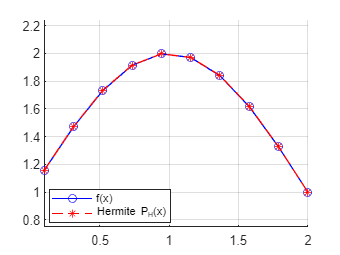


figure; 
hold on; grid on;

plot(xx, exact, 'bo-', 'DisplayName','f(x)');
plot(xx, Hs,   'r*--','DisplayName','Hermite P_H(x)');
legend('Location','best');
axis equal;